# Main File Year1

**Load Car Parameters**

project_start; 

**Choose a scenario and sensor configuration**

**Mcity**

Run this If MCity, otherwise comment out

% [scenario,scenarioName,sensors]=loadMCity();

**Other** **scenarios**

Run these commands if you are picking a non-MCity scenario or creating your own. Else comment it out.

Ignore warnings. Make sure the scenario you have created using Driving Scenaios Designer includes a sensor configuration, else errors out. The scenario needs to be in scenarios folder.

[allData, scenario, sensors,scenarioName]=choose_scenario();

assignin('base','Ts', 0.05); % sampling time (0.05sec)
stopTime=allData(end).Time;
assignin('base','StopTime',stopTime); % simulation stop time (sec)
load("SceneLabels.mat"); % Intersection, stop sign are labelled for scene 4_way, might not be relevant

**Finds number of traffic lights and stop signs and their locations**

[TL_ID,stopSign_ID]=findActorID(scenario);
restart(scenario); 

**Loads Setup required parameters for INS sensors and Vehicle Dynamics**

load('BusActorState');
assignin('base','BusActorState', BusActorState);
load('BusINSMeas');
assignin('base','BusINSMeas', BusINSMeas);

scenarioLocation=append(fullfile(homedir,'scenarios',scenarioName),'.mat');
session=load(scenarioLocation);

**Path Planning**

Run only if Mcity Scenario. Choose 2 waypoints, press enter. Blue points highlighted are the new waypoints to execut the path which replaces the predefined points in the Mcity Scenario. Stores in [xp yp].

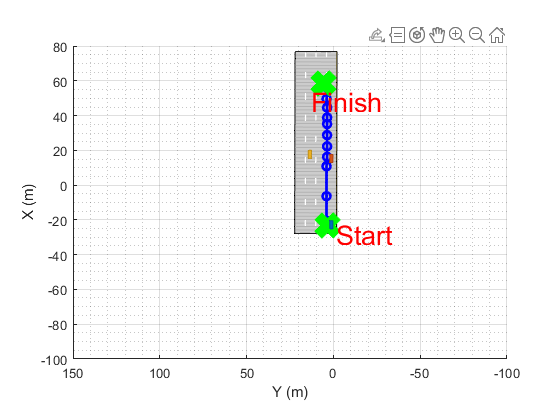

% load('Part_of_MCity.mat');
load('xpts.mat'); % Has center lanes for whole map, might have to modify
load('ypts.mat');
load('Mcity_Digraph.mat'); % Nodes and edges informationstored for Mcity
load('edgesptsv1.mat');

% scenario = drivingScenario;
% roadNetwork(scenario,'OpenDRIVE','minimcity.xodr');

plot(scenario);
hold on
p=plot(G,'XData',x,'YData',y,'EdgeColor','r','LineWidth',2,'MarkerSize',6,'NodeColor','r','ArrowSize',10);
ylim([-100 150])
xlim([-100 80])
%view([0 90])

% Finding nearest edge and path selection
[x1,y1] = getpts;

for j = 1:2 % 1 = starting point, 2 = destination
    for q = 1:numnodes(G)%numedges(G)
        NodeDist(q,j) = norm([x1(j)-x(q) y1(j)-y(q)]);
    end
end
[val,indx] = sort(NodeDist,'ascend');
for q = 1:length(indx)
    if any(eq(G.Edges.EndNodes(:,1),indx(q,1)))
        StartPoint = indx(q,1);
        break
    end
end
for q = 1:length(indx)
    if any(eq(G.Edges.EndNodes(:,2),indx(q,2)))
        EndPoint = indx(q,2);
        break
    end
end

[OptPath,len] = shortestpath(G,StartPoint,EndPoint,'Method', 'positive');

highlight(p,OptPath,'EdgeColor','blue','LineWidth',4,'ArrowSize',10);
plot(x1,y1,'x','color','g','MarkerSize',20,'linewidth',8);
ylim([-100 150])
xlim([-100 80])
pause(1)

delete(p)

% waypoint concatanation
xp=[];
yp=[];
for j=1:length(OptPath)-1
    source=OptPath(j);
    dest=OptPath(j+1);

    for i=1:length(edges)
        if edges(i).source == source & edges(i).target==dest

            %concatination
           xpoints=transpose(edges(i).x);
           ypoints=transpose(edges(i).y);

           xp=[xp xpoints];
           yp=[yp ypoints];
        end   
    end    
end 


hold on

plot(xp,yp,'-o','color','b','linewidth',2);
plot(x1,y1,'x','color','g','MarkerSize',20,'linewidth',8);
ylim([-100 150])
xlim([-100 80])
text(x1(1)-5,y1(1)-5,'Start','Color','red','FontSize',20);
text(x1(2)-10,y1(2)+7,'Finish','Color','red','FontSize',20);
%view([0 90])
hold off

**Define Ego Vehicle Waypoints**

**Run If Mcity:**

EgoWayPts = [xp' yp' zeros(length(xp),1)];
xRef = EgoWayPts(:,1);
yRef = -EgoWayPts(:,2);

**Run for Other scenarions:**

% ref=load('scenarios/scenario_SS_TL_junction.mat');
% EgoWayPts=ref.data.ActorSpecifications.Waypoints
EgoWayPts = session.data.ActorSpecifications(1,1).Waypoints; % all other actor waypoints can be gotten the same way
xRef = EgoWayPts(:,1);
yRef = -EgoWayPts(:,2);

**Calculating reference pose vectors**

**Initial location of vehicle**

X_o = xRef(1); % initial vehicle position in x direction
Y_o = yRef(1); % initial vehicle position in y direction

**Based on how far the vehicle travels, the pose is generated using 1-D lookup tables**

% calculate distance vector
distancematrix = squareform(pdist(EgoWayPts));
distancesteps = zeros(length(EgoWayPts)-1,1);
for i = 2:length(EgoWayPts)
    distancesteps(i-1,1) = distancematrix(i,i-1);
end
totalDistance = sum(distancesteps); % Total distance travelled [ x y C ] 200x4
distbp = cumsum([0; distancesteps]); % Distance for each waypoint
gradbp = linspace(0,totalDistance,100); % Linearize distance

% linearize X and Y vectors based on distance
xRef2 = interp1(distbp,xRef,gradbp);
yRef2 = interp1(distbp,yRef,gradbp);
% yRef2s = smooth(gradbp,yRef2); % smooth waypoints
% xRef2s = smooth(gradbp,xRef2); % smooth waypoints
yRef2s = yRef2';
xRef2s = xRef2';

**Theta (heading) = orientation angle of the path at reference points **

thetaRef = zeros(length(gradbp),1); 
for i = 2:length(gradbp)
    thetaRef(i,1) = atan2d((yRef2s(i)-yRef2s(i-1)),(xRef2s(i)-xRef2s(i-1)));
end
thetaRef(1) = thetaRef(2);
thetaRefs = smooth(gradbp,thetaRef); % smooth of theta
psi_o = thetaRefs(2)*(pi/180); % initial yaw angle

**Reference Plots**

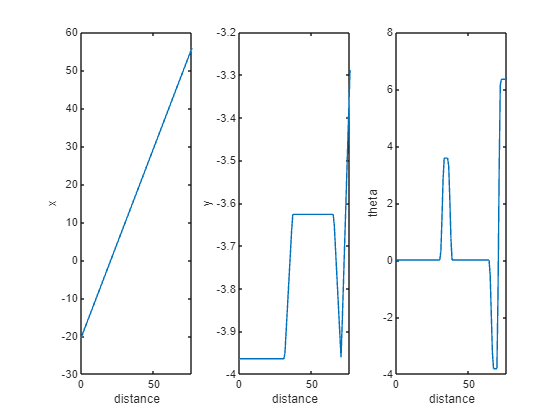

figure(1);
subplot(1,3,1);
plot(gradbp,xRef2s);
xlabel('distance'); ylabel('x')
subplot(1,3,2);
plot(gradbp,yRef2s);
xlabel('distance'); ylabel('y')
subplot(1,3,3);
plot(gradbp,thetaRefs)
xlabel('distance');ylabel('theta');

**Create direction vector**

direction = ones(length(gradbp),1);
EgoRefPose = [xRef2s,yRef2s,thetaRefs];

**Calculate curvature vector**

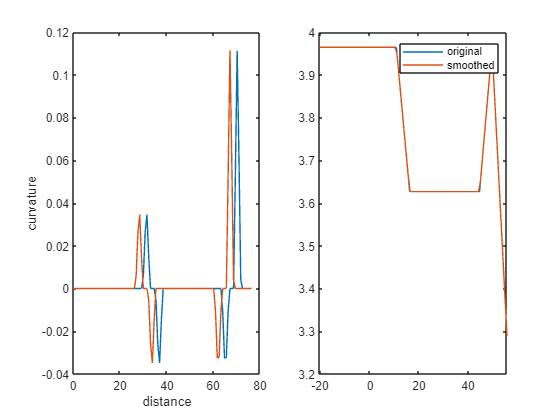

curvature = getCurvature(xRef2s,yRef2s);
curvature1 = curvature';
r = 1./abs(curvature1);
VelProfile = min(15,sqrt(9.81*r.*0.7));

curvatureAhd = zeros(1,length(curvature));
q = 5;
curvatureAhd(1:length(curvature) - q + 1) = curvature(q:end);

figure(2); 
subplot(1,2,1);
plot(gradbp,curvature)
hold on
plot(gradbp,curvatureAhd)
hold off
xlabel('distance')
ylabel('curvature')

subplot(1,2,2);
plot(xRef,-yRef)
hold on
plot(xRef2s,-yRef2s)
hold off
legend('original','smoothed')

**Run Section after simulation for visulation on Cuboid Environment**

figure
plot(out.SimStopTime,out.Refvels,'r','LineWidth',2)

Unable to resolve the name 'out.SimStopTime'.

hold on
plot(out.SimStopTime,out.EgoVel,'g','LineWidth',2)
hold off
ylim([0 15])
legend('Reference Speed', 'EgoVehicle Speed (Stanley)')
grid on
ylabel('Speed(m/s)')
xlabel('Time(s)') % Set Speed = 10 m/s (~22.4 miles/hr)


posr = out.RefPoseSim;
posc = out.EgoPose1;
Str = out.StrAngCmd;
Tstan = out.SimStopTime;
% posrPP = out.RefPoseSim;
% PPposc = out.EgoPose1;
% StrPP = out.StrAngCmd;
% Tpp = out.SimStopTime;

figure
clf
plot(scenario)
hold on
p1 = plot(xRef2s,-yRef2s,'b','LineWidth',2);
p2 = plot(posc(:,1),-posc(:,2),'g','LineWidth',2);
p3 = plot(PPposc(:,1),-PPposc(:,2),'b','LineWidth',2);
legend([p1 p2 p3],'Reference Path','Stanley Controller','Pure Pursuit Controller')
hold off


% figure
% clf
% plot(scenario)
% hold on
% h1 = animatedline('Color','r');
% h2 = animatedline('Color','b');
% 
% for j = 1:length(posr)
%    addpoints(h1,posr(j,1),-posr(j,2))
%    addpoints(h2,posc(j,1),-posc(j,2))
%    drawnow limitrate
% %    pause(0.01)
% end
% hold off

poserror = zeros(length(posr),1);
PPposerror = zeros(length(posrPP),1);
thetaerror = zeros(length(posr),1);
PPthetaerror = zeros(length(posrPP),1);



% WPdist = zeros(length(EgoRefPose),1);
% for j = 1:length(posc)
%     for q = 1:length(EgoRefPose)
%         WPdist(q) = norm(posc(j,1:2) - EgoRefPose(q,1:2));
%     end
%     [val,indx] = min(WPdist);
%     poserror(j) = norm(EgoRefPose(indx(1),1:2) - posc(j,1:2));
%     thetaerror(j) = abs(EgoRefPose(indx(1),3) - posc(j,3));
% end

WPdist = zeros(length(posr),1);
for j = 1:length(posr)
    for q = 1:length(posr)
        WPdist(q) = norm(posc(j,1:2) - posr(q,1:2));
    end
    [val,indx] = sort(WPdist,'ascend');
    poserror(j) = norm(posr(indx(1),1:2) - posc(j,1:2));
    thetaerror(j) = abs(posr(indx(1),3) - posc(j,3));
end

WPdistPP = zeros(length(posrPP),1);
for j = 1:length(posrPP)
    for q = 1:length(posrPP)
        WPdistPP(q) = norm(PPposc(j,1:2) - posrPP(q,1:2));
    end
    [val,indx] = sort(WPdistPP,'ascend');
    PPposerror(j) = norm(posrPP(indx(1),1:2) - PPposc(j,1:2));
    PPthetaerror(j) = abs(posrPP(indx(1),3) - PPposc(j,3));
end

figure
subplot(3,1,1)
plot(Tstan(1:8118),poserror(1:8118),'g','LineWidth',2)
hold on
plot(Tpp(1:4473),PPposerror(1:4473),'b','LineWidth',2)
hold off
ylabel('Position Error')
subplot(3,1,2)
plot(Tstan,thetaerror,'g','LineWidth',2)
hold on
plot(Tpp,PPthetaerror,'b','LineWidth',2)
hold off
ylabel('Theta Error')
subplot(3,1,3)
plot(Tstan,Str,'g','LineWidth',2)
hold on
plot(Tpp,StrPP,'b','LineWidth',2)
hold off
ylabel('StrAngCmd')

figure
plot(Tstan,abs(posr(:,3)),'r','LineWidth',2)
hold on
plot(Tstan,posc(:,3),'g','LineWidth',2)
plot(Tpp,PPposc(:,3),'b','LineWidth',2)
hold off
legend('ThetaRef','Theta (Stanley)','Theta (Pure Pursuit)')

**Simulate model, Plot the sensor configs, chase plot and birds eye view**

% [allData_s, scenario_s, sensors_s] = scenario_SS_TL_junction()
% egoID=session.data.EgoCarId;
% PlotterHelper(scenario_s,sensors_s,planner_wpts,ptLabels,EgoWayPts,egoID);

modelName='Predefined_with_GroundTruth_mod22';
model=append(modelName,'.slx');
open(model);
set_param(append(modelName,'/Scenario Reader'),'ScenarioFileName',scenarioLocation);
restart(scenario);
sim('Predefined_with_GroundTruth_mod22');
% simOut=sim('Predefined_with_GroundTruth_mod1');
% % egopose=simOut.logsout.getElement('EgoPose');
% % egopose1 = zeros(length(egopose.Values.Data),2);
% % simOut=sim('Predefined_with_GroundTruth_mod');
% % egowp=simOut.get('EgoPose');
% % egovel=simOut.get('EgoVel');

% for j = 1:length(out.EgoPose1.Data)
%     egoway(j,1:3) = out.EgoPose1.Data(:,:,j);
%     egoway(j,2) = - egoway(j,2);
% end
% egospeed = out.EgoVel.Data;


% egospeed = out.EgoVel;
% egoway = out.EgoPose1;
egospeed = zeros(length(out.SimVel),1);
for j = 1:length(egospeed)
    egospeed(j) = norm(out.SimVel(j,1:2));
end
egoway = out.SimPos;
egoway(:,2) = egoway(:,2);
% egoout_bus_info = Simulink.Bus.createObject(egoout);
% egoout_bus = evalin('base', egoout_bus_info.busName);
% sim('Predefined_with_GroundTruth.slx');

[allData_s, scenario_s, sensors_s] = Simulated_Scenario(egoway,egospeed);
% StopTime = out.SimStopTime(end);
scenario_s.StopTime = out.EgoPose.Position.Time(end);%out.SimStopTime(end);
% restart(scenario_s);
% egoID=session.data.EgoCarId;
% drivingScenarioDesigner(scenario_s)
% labels = {'TrafficLight','StopSign','RailRoadCrossing','RoundAbout'};
ptLabelstext = {'SS','TL','SS','RA','RC','SS'};
planner_wpts = SceneInfo(:,1:2);
PlotterHelper(scenario_s,sensors_s,planner_wpts,ptLabelstext,egoway,1);

**SIL simulations**

%helperSIL(model,modelName);

**For Trajectory Generation**

function coeffVec = generateCubicCoeffs(posPts, velPts, finalTime)
x0 = posPts(1);    dx0 = velPts(1);    xT = posPts(2);    dxT = velPts(2);
coeffVec = [x0 dx0 0 0]';
TMat0 = [1 finalTime; 0 1];    B = [xT; dxT] - TMat0*coeffVec(1:2);

invTMatF = [3/finalTime^2 -1/finalTime;  -2/finalTime^3 1/finalTime^2];    
coeffVec(3:4) = invTMatF * B;
coeffVec = fliplr(coeffVec');
end

function [q, qd, qdd, pp] = viapt(wayPoints, timePoints, t, varargin)    
narginchk(3,5)
if nargin > 3        
    charInputs = cell(1,2);        
    [charInputs{:}] = convertStringsToChars(varargin{:});
else        
    charInputs = {};
end
validateattributes(wayPoints, {'numeric'},{'2d','nonempty','real','finite'}, 'cubicpolytraj','wayPoints');    
validateattributes(timePoints, {'numeric'}, {'nonempty','vector','real','finite','increasing','nonnegative'},'cubicpolytraj','timePoints');
timePoints = timePoints(:)';
n = size(wayPoints,1);    p = size(wayPoints,2);
names = {'VelocityBoundaryCondition'};    defaults = {zeros(n,p)};    parser = robotics.core.internal.NameValueParser(names, defaults);    parse(parser, charInputs{:});    velBC = parameterValue(parser, names{1});
coder.internal.errorIf(length(timePoints) ~= p,'shared_robotics:robotcore:utils:WayPointMismatch');
coder.internal.errorIf(size(velBC,1) ~= n || size(velBC,2) ~= p,'shared_robotics:robotcore:utils:WaypointVelocityBCDimensionMismatch');
q = zeros(n, length(t));    qd = zeros(n, length(t));    qdd = zeros(n, length(t));
coeffdim = 4;    coefMat = zeros((p-1)*n,coeffdim);
for i = 1:p-1
    finalTime = timePoints(i+1) - timePoints(i);
     coeffMat = zeros(n,coeffdim);
     for j = 1:n            
         coeffMat(j,:) = generateCubicCoeffs(wayPoints(j,i:i+1),velBC(j, i:i+1), finalTime);
         cidx = (i-1)*n + j;            
         coefMat(cidx, :) = coeffMat(j,:);
     end
end
[modBreaks, modCoeffs]=robotics.core.internal.addFlatSegmentsToPPFormParts(timePoints,coefMat,n);
pp = mkpp(modBreaks, modCoeffs, n);    q(:,:) = ppval(pp, t);
if nargout > 1
    derivativeBreaks=robotics.core.internal.changeEndSegBreaks(modBreaks,t);
    dCoeffs = robotics.core.internal.polyCoeffsDerivative(modCoeffs);        ppd = mkpp(derivativeBreaks, dCoeffs, n);        qd(:,:) = ppval(ppd, t);
end
if nargout > 2
    ddCoeffs = robotics.core.internal.polyCoeffsDerivative(dCoeffs);        
    ppdd = mkpp(derivativeBreaks, ddCoeffs, n);        
    qdd(:,:) = ppval(ppdd, t);
end
end

**Curvature Function**

function curvature = getCurvature(xRef,yRef)
% Calculate gradient by the gradient of the X and Y vectors
DX = gradient(xRef);
D2X = gradient(DX);
DY = gradient(yRef);
D2Y = gradient(DY);
curvature = (DX.*D2Y - DY.*D2X) ./(DX.^2+DY.^2).^(3/2);
end